N_T = 0.1570; % 系数

sensor_n = 5; % 传感器行列数
sensor_interval = 0.005; % 传感器间隔
sensor_N = sensor_n^2; % 传感器数量N
sensor_pos = zeros(sensor_N,3); % 传感器位置
for i = 1:sensor_n % y
    for j = 1:sensor_n % x
        sensor_pos((i-1)*sensor_n + j,1)=((j-1)-(sensor_n-1)/2)*sensor_interval;   % x
        sensor_pos((i-1)*sensor_n + j,2)=((i-1)-(sensor_n-1)/2)*sensor_interval;   % y
        sensor_pos((i-1)*sensor_n + j,3)=0;                                        % z
    end
end
Bl = zeros(sensor_N,3);
Bl_compensate = zeros(sensor_N,3);

delete(instrfindall);

ser = serialport('COM19',115200); % 打开串口

Bl_compensate = serial_parse(ser, sensor_N);

Try read serialport times: 1


delete(ser); % 关闭串口

delete(instrfindall);

ser = serialport('COM19',115200); % 打开串口

Bl = serial_parse(ser, sensor_N); % 读取磁场值

Try read serialport times: 1

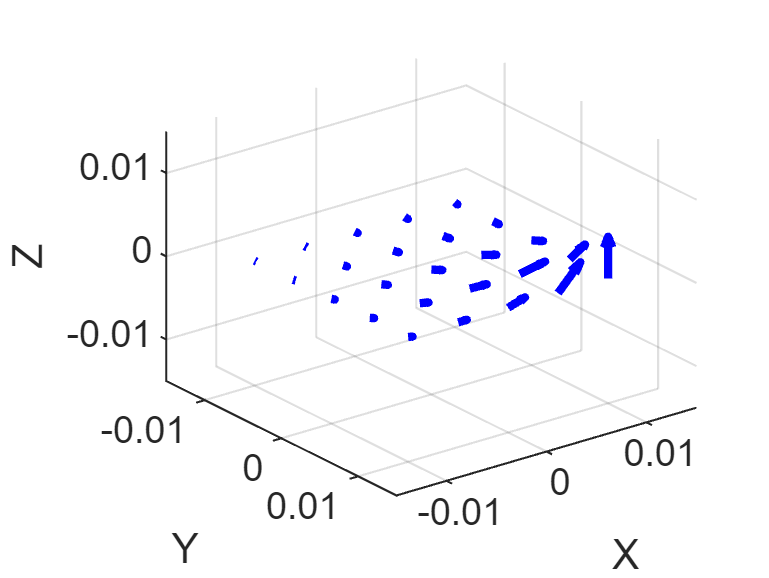


Bl(:,1) = - Bl(:,1) + Bl_compensate(:,1); % 地磁场补偿
Bl(:,2) = Bl(:,2) - Bl_compensate(:,2);
Bl(:,3) = Bl(:,3) - Bl_compensate(:,3); % Z轴与X、Y相反

quiver3(sensor_pos(:,1),sensor_pos(:,2),sensor_pos(:,3),Bl(:,1),Bl(:,2),Bl(:,3),'-b','LineWidth',2);
xlim([-0.015 0.015]);
ylim([-0.015 0.015]);
zlim([-0.015 0.015]);
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gca,'YDir','reverse');


delete(ser); % 关闭串口

init = [0 0 1 0 0 0.05]; % 优化初值
lb = []; % 上界
ub = []; % 下界
result = lsqnonlin(@(param) target_function(param,sensor_pos,Bl,N_T),init,lb,ub,[],[],[],[],@nlcon)


找到目标函数值更低的可行点。


找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


result =     0.0865   -0.0122    0.9962    0.0099    0.0099    0.0103


delete(ser);

function Bl = serial_parse(ser, N)
Bl = [];
err_cnt = 1;

while true
    flush(ser);
    stringLine = readline(ser);
    if(strncmp(stringLine,"U",1))
        newStr = strip(stringLine,"U");
        U = sscanf(newStr,"%d");


        stringLine = readline(ser);
        if(strncmp(stringLine,"V",1))
            newStr = strip(stringLine,"V");
            V = sscanf(newStr,"%d");
        end

        stringLine = readline(ser);
        if(strncmp(stringLine,"W",1))
            newStr = strip(stringLine,"W");
            W = sscanf(newStr,"%d");
        end

        if(length(U)==N && length(V)==N && length(W)==N)
            Bl(:,1) = U;
            Bl(:,2) = V;
            Bl(:,3) = W;
        end
    end

    if isempty(Bl)
        err_cnt = err_cnt + 1;
    else
        fprintf("Try read serialport times: %d", err_cnt);
        break
    end

    if err_cnt >= 10
        error("Fail too many times.")
        break
    end
end

end

function [Blx, Bly, Blz] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,x,y,z,noise)
rng default % 为了可重复性，设置默认随机数种子

Rl = sqrt((x-a)^2+(y-b)^2+(z-c)^2);
comm = 3*(m*(x-a)+n*(y-b)+p*(z-c));
Blx = N_T*((comm*(x-a))/(Rl^5)-m/(Rl^3)) + noise*randn;
Bly = N_T*((comm*(y-b))/(Rl^5)-n/(Rl^3)) + noise*randn;
Blz = N_T*((comm*(z-c))/(Rl^5)-p/(Rl^3)) + noise*randn;
end

function F = target_function(param,sensor_pos,Bl,N_T)
m = param(1);
n = param(2);
p = param(3);
a = param(4);
b = param(5);
c = param(6);
N = size(sensor_pos,1);
Bpre = zeros(N,3);
for i = 1:N
    [Bpre(i,1),Bpre(i,2),Bpre(i,3)] = MagneticFluxDensityComponent(N_T,m,n,p,a,b,c,sensor_pos(i,1),sensor_pos(i,2),sensor_pos(i,3),0);
    F((i-1)*3 + 1) = Bpre(i,1) - Bl(i,1);
    F((i-1)*3 + 2) = Bpre(i,2) - Bl(i,2);
    F((i-1)*3 + 3) = Bpre(i,3) - Bl(i,3);
end
end

function [c,ceq] = nlcon(param)
c = [];

m = param(1);
n = param(2);
p = param(3);
ceq = m^2 + n^2 + p^2 - 1;
end